# HYPEROPTIM

Compare the accuracy of various models trained with and without hyperparameter optimization.

Note that this script takes about 5 minutes to run.

## Load data

load heartdisease

## Divide the data into training and validation sets

rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'Holdout',0.2);
tridx = training(part);
tdata = heartdataNum(tridx,:);
vdata = heartdataNum(~tridx,:);

## Create a table to hold the results

none_ResubLoss = zeros([5,1]);
none_Loss = zeros([5,1]);
auto_ResubLoss = zeros([5,1]);
auto_Loss = zeros([5,1]);
mdlnames = {'kNN';'Tree';'Naive Bayes';'Discriminant Analysis';'SVM'};
results = table(none_ResubLoss,none_Loss,auto_ResubLoss,auto_Loss);
results.Properties.RowNames = mdlnames;

## *k-*NN models

m = fitcknn(tdata,'HeartDisease');
results.none_ResubLoss(1) = resubLoss(m);
results.none_Loss(1) = loss(m,vdata);

Setting '`OptimizeHyperparamters`' to 'auto' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.30409 |     0.28864 |     0.30409 |     0.30409 |           17 |    minkowski |
|    2 | Accept |     0.36257 |     0.17677 |     0.30409 |     0.30642 |           69 |      jaccard |
|    3 | Accept |     0.37427 |     0.25531 |     0.30409 |     0.32724 |            2 |   seuclidean |
|    4 | Accept |     0.33041 |     0.17221 |     0.30409 |     0.31852 |            4 |       cosine |
|    5 | Accept |     0.30409 |     0.13612 |     0.30409 |      0.3041 |           17 |    minkowski |
|    6 | Accept |     0.31579 |    0.088215 |     0.30409 |     

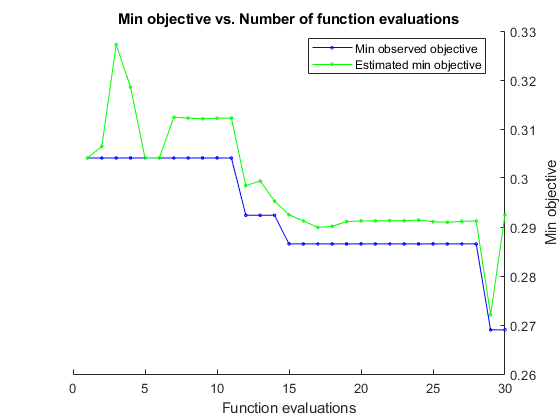

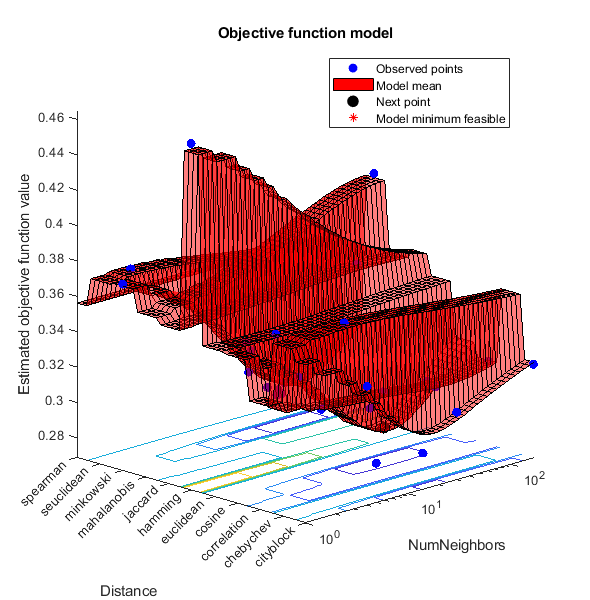

m = fitcknn(tdata,'HeartDisease','OptimizeHyperparameters','auto');

results.auto_ResubLoss(1) = resubLoss(m);
results.auto_Loss(1) = loss(m,vdata);

## Tree models

m = fitctree(tdata,'HeartDisease');
results.none_ResubLoss(2) = resubLoss(m);
results.none_Loss(2) = loss(m,vdata);

Setting '`OptimizeHyperparamters`' to 'auto' will optimize these tree properties:

- `MinLeafSize`

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.33255 |     0.28047 |     0.33255 |     0.33255 |           12 |
|    2 | Best   |     0.30679 |      0.1531 |     0.30679 |     0.31243 |           43 |
|    3 | Accept |     0.37705 |     0.15894 |     0.30679 |      0.3068 |            1 |
|    4 | Accept |     0.44731 |     0.17005 |     0.30679 |     0.31176 |          174 |
|    5 | Accept |     0.30679 |     0.19448 |     0.30679 |     0.30678 |           37 |
|    6 | Accept |     0.31382 |     0.14132 |     0.30679 |     0.30673 |           22 |
|    7 | Accept |     0.35831 |     0.15387 |     0.30679 |     0.30645 |            4 |
|    8 | Accept |    

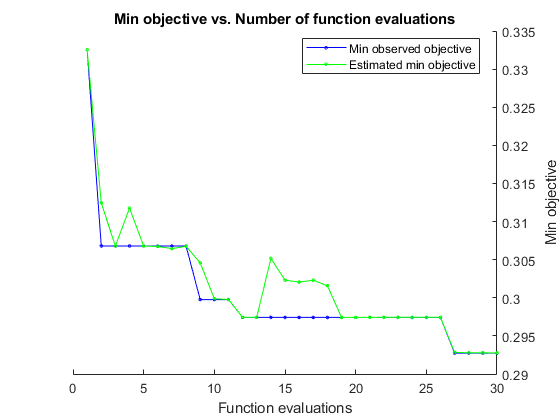

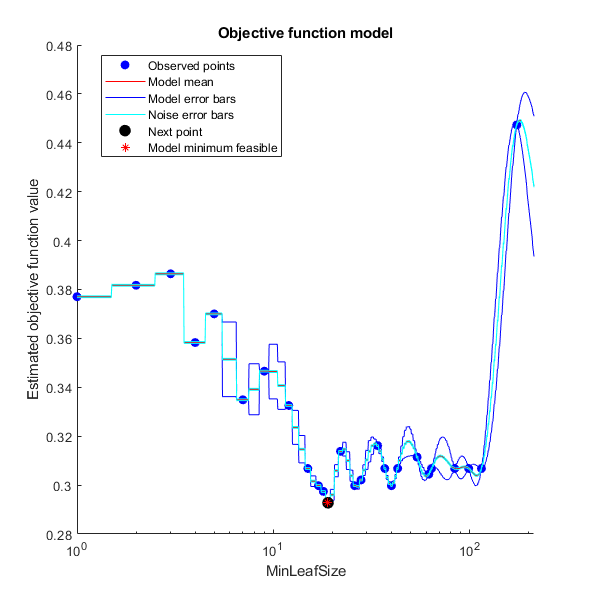

m = fitctree(heartdataNum,'HeartDisease','OptimizeHyperparameters','auto');

results.auto_ResubLoss(2) = resubLoss(m);
results.auto_Loss(2) = loss(m,vdata);

## Naive Bayes models

m = fitcnb(tdata,'HeartDisease');
results.none_ResubLoss(3) = resubLoss(m);
results.none_Loss(3) = loss(m,vdata);

Setting '`OptimizeHyperparamters`' to 'auto' will optimize these Naive Bayes properties:

- `Width`

- `DistributionNames`

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.28571 |     0.13399 |     0.28571 |     0.28571 |       normal |            - |
|    2 | Accept |     0.28571 |     0.12919 |     0.28571 |     0.28571 |       normal |            - |
|    3 | Accept |     0.30913 |     0.47696 |     0.28571 |     0.28572 |       kernel |     0.017527 |
|    4 | Accept |     0.43794 |     0.47618 |     0.28571 |     0.28572 |       kernel |      0.93592 |
|    5 | Accept |     0.30913 |     0.58719 |     0.28571 |     0.28572 |       kernel |     0.017529 |
|    6 | Accept |     0.34192 |     0.57587 |     0.28571 |     

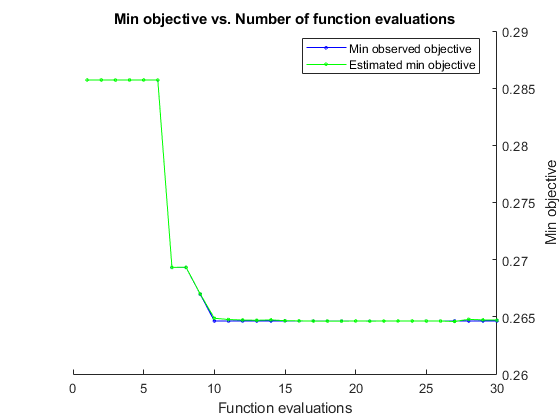

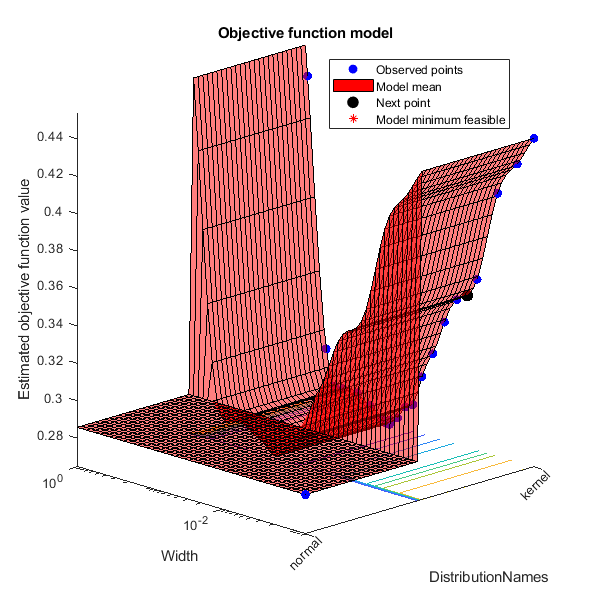

m = fitcnb(heartdataNum,'HeartDisease','OptimizeHyperparameters','auto');

results.auto_ResubLoss(3) = resubLoss(m);
results.auto_Loss(3) = loss(m,vdata);

## Discriminant Analysis models

m = fitcdiscr(tdata,'HeartDisease');
results.none_ResubLoss(4) = resubLoss(m);
results.none_Loss(4) = loss(m,vdata);

Setting '`OptimizeHyperparamters`' to 'auto' will optimize these Discriminant Analysis properties:

- `Delta`

- `Gamma`

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.29977 |     0.16962 |     0.29977 |     0.29977 |    0.0004191 |      0.91261 |
|    2 | Accept |     0.44731 |    0.088586 |     0.29977 |     0.30929 |       11.177 |      0.94961 |
|    3 | Best   |     0.26464 |    0.086814 |     0.26464 |     0.26467 |   9.2753e-05 |      0.33364 |
|    4 | Accept |     0.44731 |     0.08329 |     0.26464 |     0.26471 |       33.688 |      0.17193 |
|    5 | Accept |     0.26464 |    0.084693 |     0.26464 |     0.26463 |   1.0011e-06 |      0.17041 |
|    6 | Best   |      0.2623 |    0.087011 |      0.2623 |     

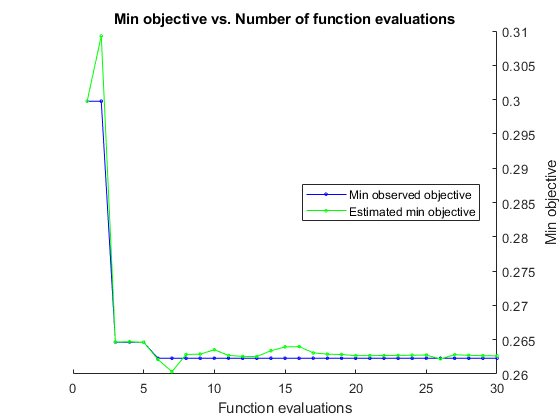

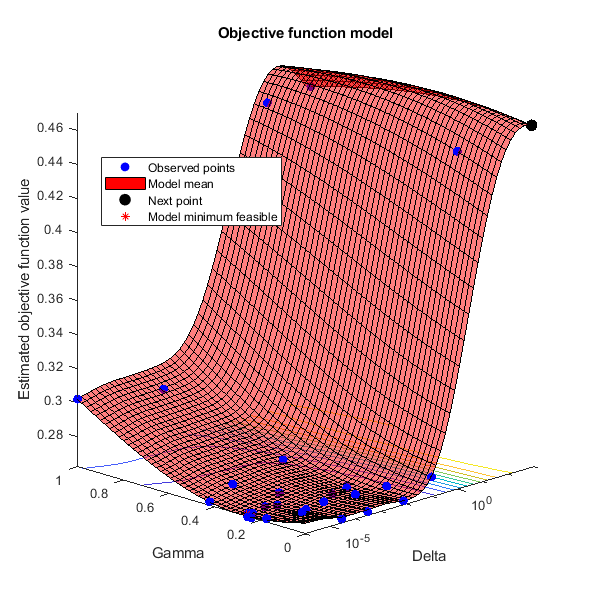

m = fitcdiscr(heartdataNum,'HeartDisease','OptimizeHyperparameters','auto');

results.auto_ResubLoss(4) = resubLoss(m);
results.auto_Loss(4) = loss(m,vdata);

## SVM models

m = fitcsvm(tdata,'HeartDisease');
results.none_ResubLoss(5) = resubLoss(m);
results.none_Loss(5) = loss(m,vdata);

Setting '`OptimizeHyperparamters`' to 'auto' will optimize these SVM properties:

- `BoxConstraint`

- `KernelScale`

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|=====================================================================================================|
|    1 | Best   |     0.44731 |      0.1783 |     0.44731 |     0.44731 |       132.09 |       249.14 |
|    2 | Accept |     0.44731 |     0.14012 |     0.44731 |     0.44731 |      0.06038 |        291.6 |
|    3 | Best   |       0.274 |      3.5853 |       0.274 |     0.27402 |       12.075 |      0.11526 |
|    4 | Accept |       0.274 |      10.274 |       0.274 |     0.27401 |     0.023693 |    0.0029351 |
|    5 | Accept |     0.27635 |     0.15274 |       0.274 |     0.27403 |    0.0011372 |      0.02569 |
|    6 | Accept |     0.45199 |      40.541 |       0.274 |     

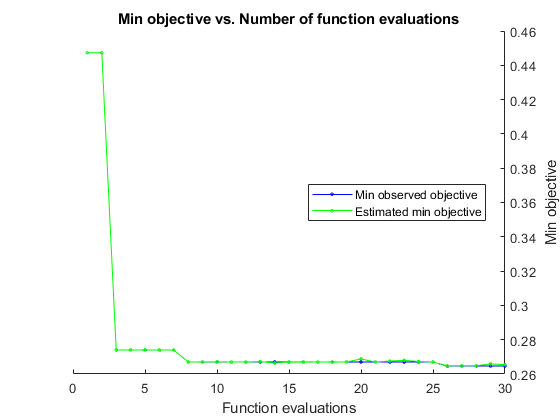

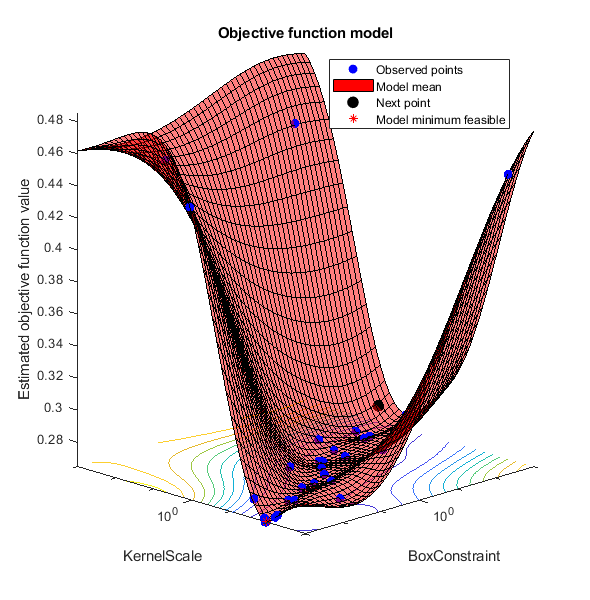

m = fitcsvm(heartdataNum,'HeartDisease','OptimizeHyperparameters','auto');

results.auto_ResubLoss(5) = resubLoss(m);
results.auto_Loss(5) = loss(m,vdata);

## View results

disp(results)

                             none_ResubLoss    none_Loss    auto_ResubLoss    auto_Loss
                             ______________    _________    ______________    _________

    kNN                             0          0.34127      0.27485            0.18831 
    Tree                     0.078947          0.28237      0.21546           0.082375 
    Naive Bayes               0.29825          0.20002      0.25293            0.14121 
    Discriminant Analysis     0.27193           0.1765      0.25527             0.1765 
    SVM                       0.30117          0.16475      0.26464            0.16474 

